# y''+y=0

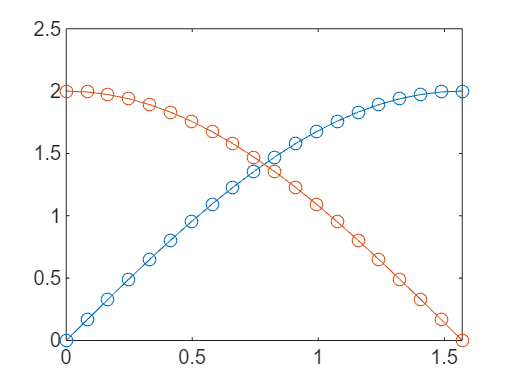

clear;clc;
dydx=@(x,y) [y(2);-y(1)];
xmesh=linspace(0,pi/2,20);
solinit=bvpinit(xmesh,[2,2]);
sol=bvp4c(dydx,@bcfcn,solinit);
plot(sol.x,sol.y,'-o')

function res=bcfcn(ya,yb) % Boundary Condition ka function
    res=[ya(1) yb(1)-2];
end

## Quiz BVP